# Delayed Feedback System for Franka Emika Panda

Add Path

clear;clc;
addpath("..\ReadYAML\")
addpath("Visualization\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q} (t)\right) \ddot{\vec{q}} (t) + G \left( \vec{q} (t) \right) = - K_{p} \left( \vec{q} \left( t - \frac{3}{2} t_{s} \right) - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} \left( t - \frac{3}{2} t_{s} \right) - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Dimension

config_mapping.dimension=7;

Precision and truncation rank

config_mapping.precision=30;
config_mapping.trunc_rank=-1;

Target Position

config_mapping.target=config.TargetAngle';

Gains

config_mapping.K_p=diag(config.Kp);
config_mapping.K_d=diag(config.Kd);

Matrix Expontent Method

config_mapping.MatExpOpt="jordan";

Visualization of rank of $\mathcal{A}^i$

config_mapping.visual_Acal_rank=50;

## Discretization

Start Computing M_d
历时 0.094430 秒。
Done
Start Computing K_G
历时 0.238234 秒。
Done
Start Computing K_f
历时 0.001698 秒。
Done
Start Computing A
历时 0.002181 秒。
Done


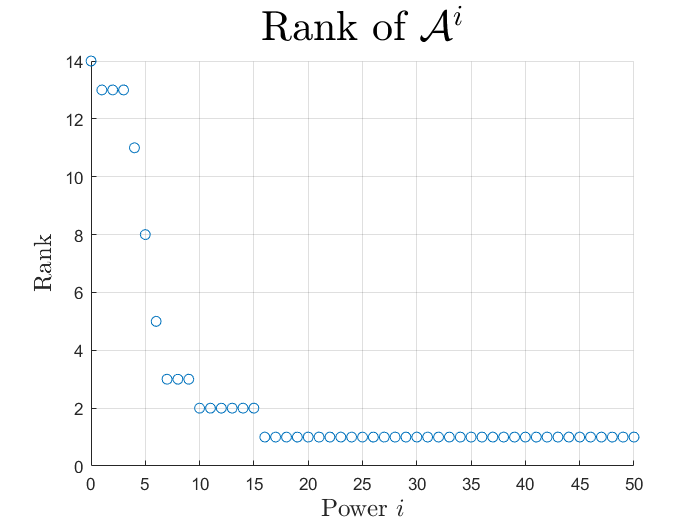

Start Computing B
历时 53.249748 秒。
Done
Start Compiling W
历时 0.001017 秒。
Done


ts=1e-3;
% ts=7.87e-3;
result_discretization=DiscreteMapping(ts,config_mapping);

## Visualization

Eigen Properties

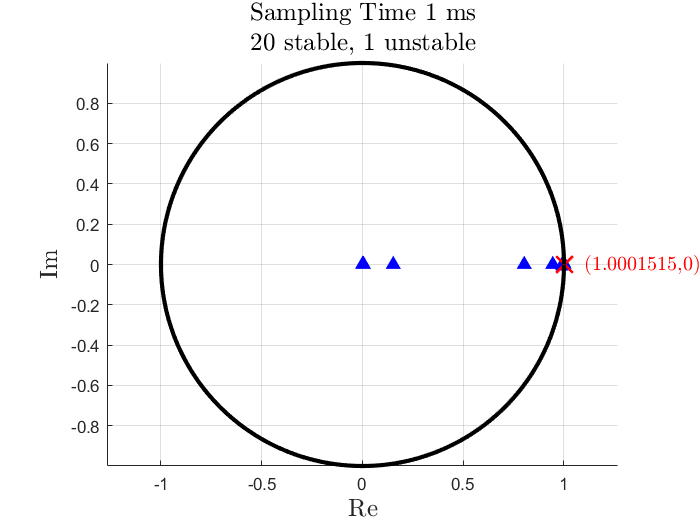

eig_data=eig(result_discretization.W,"balance","vector");
% eig_data=round(eig_data*1000)/1000;
% eig_data=vpa(eig_data,5)
show_eig(eig_data, true, ts)

disp(vpa(eig_data,config_mapping.precision))

$$\left(\begin{array}{c} 0.152753000110612435769041894673\\ 0.80263943510338664477643533246\\ 0.000465264985849478396318090744899\\ 0.00505100634531595836518302888862\\ 0.00504353681432820766944447044011\\ 0.00506531557291816075111468009595\\ 0.00177177674565039394022347707391\\ 0.00195365737481859426741270802097\\ 0.00203508811332622817705240159114\\ 0.944255416622884147237471097469\\ 0.997265667565051971976686218113+0.00793734306852530470399731399311\,\mathrm{i}\\ 0.997265667565051971976686218113-0.00793734306852530470399731399311\,\mathrm{i}\\ 0.996635674471920474104535969673+0.0070109577651153104707604235557\,\mathrm{i}\\ 0.996635674471920474104535969673-0.0070109577651153104707604235557\,\mathrm{i}\\ 0.996030854582188873713732846227+0.00592910375926145472719186457766\,\mathrm{i}\\ 0.996030854582188873713732846227-0.00592910375926145472719186457766\,\mathrm{i}\\ 0.994597805201503537553264777671+0.00429584711107703579729966136824\,\mathrm{i}\\ 0.994597805201503537553264777671-0.00429584711107703579729966136824\,\mathrm{i}\\ 0.998347929029927527722065860871\\ 0.999958989299642553305602632463\\ 1.0001514764894099407399608026 \end{array}\right)$$

Norm of $W^i \vec{v}$

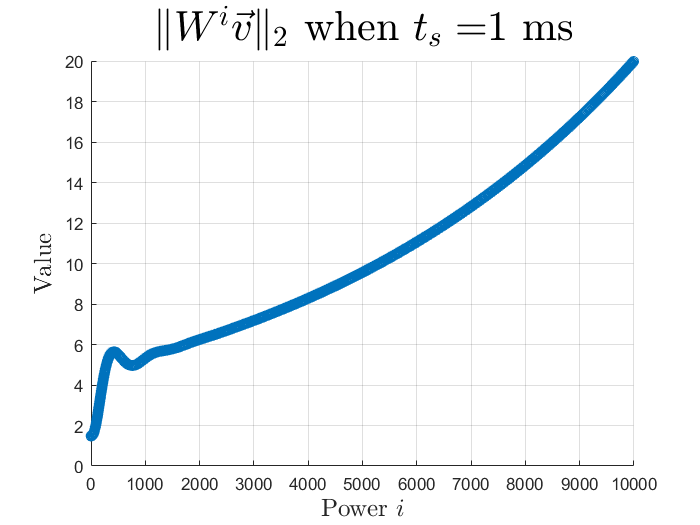

vec_test=0.01*ones(21,1);
modulus_data=zeros(10000,1);
for i=1:length(modulus_data)
    modulus_data(i)=norm(mpower(result_discretization.W,i)*vec_test);
end
scatter(1:length(modulus_data),modulus_data)
grid on
title("$\Vert W^{i} \vec{v} \Vert_{2}$ when $t_s=$" + ...
    num2str(1000*ts)+" ms", "FontSize",25,"Interpreter","latex")
xlabel("Power $i$","Interpreter","latex","FontSize",15)
ylabel("Value","Interpreter","latex","FontSize",15)